# Solving Differential equations

We've coded up a general way to solve differential equations in the form


$$\dot{x} =A\;x\ldotp$$


## First Order Differential Equation

We wish to solve the differential equation


$$\dot{x} =-2x$$


given the initial condition $x\left(0\right)=10$.

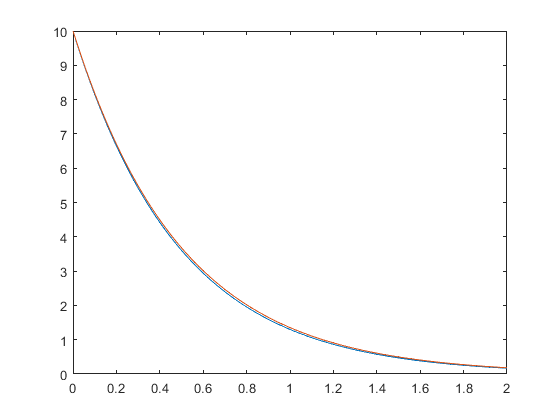

A = -2;
x0 = 10;
dT = .02;
 T = 2;

[t,X] = f_Euler(A,x0,dT,T);
plot(t,X,t,x0*exp(A*t))

The numerical solution fits the analytic solution $x\left(t\right)=10e^{-2t\;}$pretty well. However, as our sampling time $\mathrm{dT}$ becomes larger, the accuracy of the solution becomes worse.

## First Order Differential Equation

We now wish to solve the differential equation


$$\ddot{q} =-2\zeta \;\omega \;\dot{q} -\omega^2 q$$


given the initial condition $x\left(0\right)=10$ and $\dot{x} \left(0\right)=0$. This is the same RLC circuit we solved in Week 2.

We need to reduce our sytem to the form $\dot{x} =\mathrm{Ax}$, where $x$ is a vector. Do do so, we define


$$x=\left\lbrack \begin{array}{c}
q\\
\dot{q} 
\end{array}\right\rbrack$$


[Note: the size of the vector $x$ is equal to the order of the differential equation]

We now show that


$$\dot{x} =\left\lbrack \begin{array}{c}
\dot{q} \\
\ddot{q} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-2\zeta \omega \; & -\omega^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q\\
\dot{q} 
\end{array}\right\rbrack ,$$


which gives us all the information we need to compute $A$.

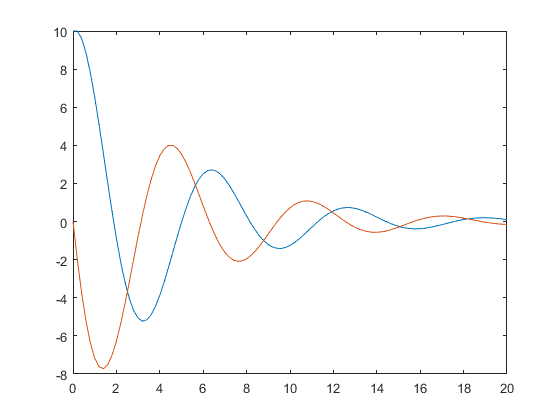

w = 1;
z = 0.3;

A = [ 0      1
     -w^2 -2*z*w];

x0 = [10; 0];
dT = 0.2;
 T = 20;

[t,X] = f_Euler(A,x0,dT,T);
plot(t,X)

Since the state $x$ is a vector with 2 elements, `plot(t,X)` provides two curves. The blue one is $q\left(t\right)$, the red one is $\dot{q} \left(t\right)$. 

If we just want $q\left(t\right)$, we should instead write

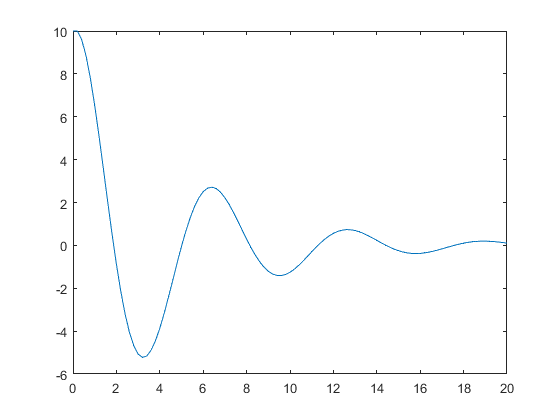

plot(t,X(1,:))

function [t,X] = f_Euler(A,x0,dT,T)

t = 0:dT:T;

N = T/dT;

I = eye(length(x0));

K0 = eye(N);
K1 = diag(ones(N-1,1),-1);


Here we create the matrix $D=K_0 \otimes I-K_1 \otimes \left(I+\mathrm{dTA}\right)$, which looks like this


$$D=\left\lbrack \begin{array}{ccccc}
I &  &  &  & \\
-\left(I+\mathrm{dT}\;A\right) & I &  &  & \\
 & -\left(I+\mathrm{dT}\;A\right) & \;\;\;\;\;\;I &  & \\
 &  & \;\;\;\;\;\;\ddots  & \ddots \; & \\
 &  &  & -\left(I+\mathrm{dT}\;A\right) & I
\end{array}\right\rbrack$$


D = kron(K0,I)+kron(K1,-(I+dT*A));

The vector $e$ should instead look like


$$e=\left\lbrack \begin{array}{c}
\left(I+\mathrm{dT}\;A\right)\\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


e = zeros(size(D,1),1);
e(1:length(x0)) = (I+dT*A)*x0;

X = D\e;
X = [x0 reshape(X,[length(x0),N])];

end